**The cart and pole system**

Consider the cart-and-pole system here depicted:

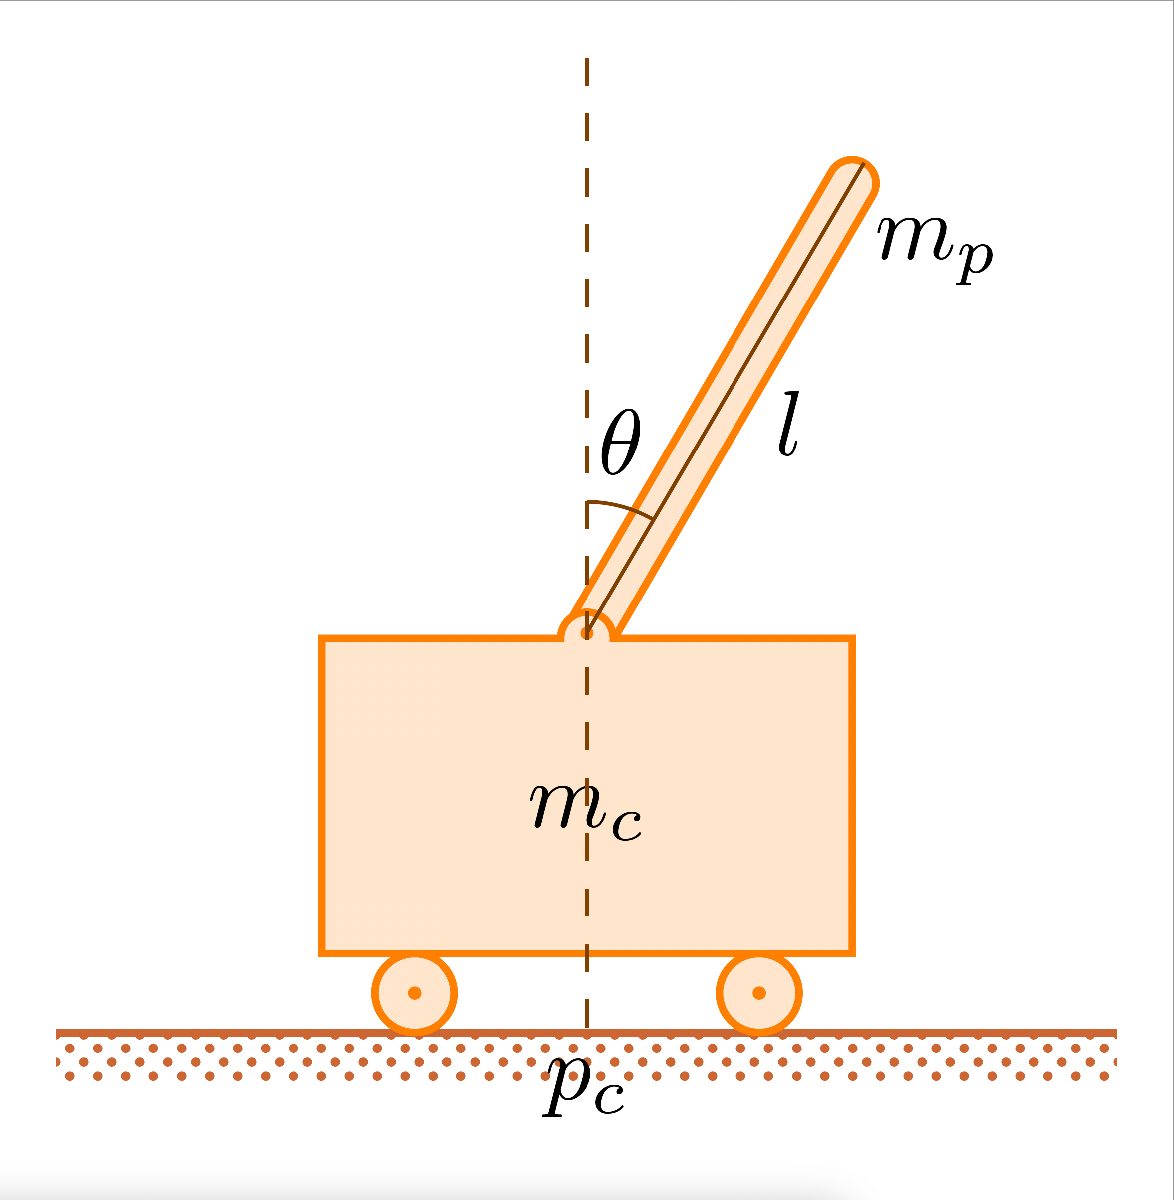

whose dynamics follows the following equations:


$$\ddot{\theta}=\frac{g \sin(\theta)\,+\,\cos(\theta) \left[ \frac{-F\,-\,m_p\,l\,\dot{\theta}^2 \sin \left(\theta\right)\,+\,\mu_c\,\text{sgn}\left(\dot{p}_c\right)}{m_c\,+\,m_p}\right]-\frac{\mu_p\dot{\theta}}{m_p\,l}}{l\,\left[\frac{4}{3}-\frac{m_p\,cos^2\left(\theta\right)}{m_c\,+\,m_p}\right]}$$
   


$$(*)$$


$  \ddot{p}_c=\frac{F\,+\,m_p\,l\,\left[\dot{\theta}^2\,\sin\left(\theta\right)\,-\,\ddot{\theta}\,\cos(\theta)\right]}{m_c\,+\,m_p}$

where $g = 9.8\,\text{m/sec}$ is the gravitational acceleration, $m_c = 1\,\text{kg}$ is the cart mass, $m_p = 0.1\,\text{kg}$ is the pole mass, $l = 0.5\,\text{m}$ is the half-pole length, $\mu_p = 0.000002$ is the pole on cart friction coefficient, and $F:|F|\leq 10\,\text{N}$ is the force applied to cart's center of mass.

1. Clearly define an optimal control problem for pole balancing.

% Arguing the answer


Optimal control consists to keep the pole vertical, perpendicular to the cart and within  a certain range $\Delta$ around $\theta =0$°, starting from an initial condition. 

First of all we need to check if it's possible to reach and observe state we are considering, that is the zero state , so taking into account the study of observability and reachability of the system but after linearization and discretization.

Applying so infinite horizon LQR and find the optimal controller to reach the desired state and keep it there for some amount of time

2. Is the LQR applicable in its simple form on the system? If not what is missed?

% Arguing the answer both in case of positive and negative answer

In order to apply the LQR ,that operates with a dynamic sistem at minimun cost described by quadratic function,  the system considered has to be linear and time invariant.

So first linearization has to be applied.

Secondly choose one matrix that is semidefinite positive $Q$, $Q_H
$ and one definite positive $R$ so that optimal control input , $\pi^* (x^k)$ solution 


$$argmin_{\pi}  \,\,  \sum_{k=0}^{+\infty}
{x^{k}}^{T}  Q  {x^{k}}+{u^k}^T R u^k
$$



$$x^{k+1}=Ax^k+Bu^k$$



$$x^0=x_{in} \,\,\,x^{\infty}=0
$$


can be found

In addition state has to be accessible or at least $(A,C)$ observable, and very important the state $x=0

$ must be (A,B) fully reachable.

3. Design an LQR for the linearized version of the cart and pole obtained in the previous hands-on. Justify all the design choices and perform all the required checks

% first part will be the same as the point 4 of previous hand on.
%Practically the first part consists in linearization and then
%discretization

clear all 
close all
clc                 % cleaning the workspace
sympref('default')

ans = struct with fields:
           FourierParameters: [1    -1]
           HeavisideAtOrigin: 1/2
            AbbreviateOutput: 1
               TypesetOutput: 1
         FloatingPointOutput: 0
      PolynomialDisplayStyle: 'default'
    MatrixWithSquareBrackets: 0


syms theta dt pc dpc
format short
syms u g mc mp l mu_p

syms f1(theta, dt, pc , dpc) f2(theta, dt, pc , dpc)


f1(theta, dt, pc , dpc)=(((g*sin(theta)+cos(theta)*(((-u-mp*l*(dt^2)*sin(theta))/(mc+mp)))-(mu_p*dt)/(mp*l)))/(l*(4/3-(mp*(cos(theta)^2)/(mc+mp)))));

f2(theta, dt, pc , dpc)=(u+mp*l*(((dt)^2)*sin(theta)-(f1(pc, dpc, theta, dt))*cos(theta)))/(mc+mp);
f_x=jacobian([dt;f1;dpc;f2],[theta;dt;pc;dpc]);
g_x=jacobian([dt;f1;dpc;f2],[u]);

%evaluating A matrix after linearization

pc=0;
dpc=0;
theta=0;
dt=0

dt = 0

A1=eval(f_x)

$$A1 = \begin{array}{l} \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ -\frac{g}{l\,\sigma_{1}} & \frac{\mu_{p}}{l^{2}\,\mathrm{mp}\,\sigma_{1}} & 0 & 0\\ 0 & 0 & 0 & 1\\ 0 & 0 & \frac{g\,\mathrm{mp}}{\left(\mathrm{mc}+\mathrm{mp}\right)\,\sigma_{1}} & -\frac{\mu_{p}}{l\,\left(\mathrm{mc}+\mathrm{mp}\right)\,\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\mathrm{mp}}{\mathrm{mc}+\mathrm{mp}}-\frac{4}{3} \end{array}$$

B1=eval(g_x)

$$B1 = \left(\begin{array}{c} 0\\ \frac{1}{l\,\left(\mathrm{mc}+\mathrm{mp}\right)\,\left(\frac{\mathrm{mp}}{\mathrm{mc}+\mathrm{mp}}-\frac{4}{3}\right)}\\ 0\\ -\frac{\frac{\mathrm{mp}}{\left(\mathrm{mc}+\mathrm{mp}\right)\,\left(\frac{\mathrm{mp}}{\mathrm{mc}+\mathrm{mp}}-\frac{4}{3}\right)}-1}{\mathrm{mc}+\mathrm{mp}} \end{array}\right)$$




%evaluated also in the second equilibrium state
n=size(A1)

n =      4     4


value=[g, mp, mc, mu_p, l];
A1=double(subs(A1,value,[9.8 0.1 1 0.000002 0.5]))

A1 =          0    1.0000         0         0
   15.7756   -0.0001         0         0
         0         0         0    1.0000
         0         0   -0.7171    0.0000



B1=double(subs(B1,value,[9.8 0.1 1 0.000002 0.5]))

B1 =          0
   -1.4634
         0
    0.9756


C=eye(length(A1))

C =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


%defining the C matrix as follow so the unique outputs of the system are
%angle and position
sys=ss(A1,B1,C,0)

sys =
 
  A = 
               x1          x2          x3          x4
   x1           0           1           0           0
   x2       15.78  -6.439e-05           0           0
   x3           0           0           0           1
   x4           0           0     -0.7171   2.927e-06
 
  B = 
           u1
   x1       0
   x2  -1.463
   x3       0
   x4  0.9756
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
 
Continuous-time state-space model.



sysTD=c2d(sys, 0.02) %discretization

sysTD =
 
  A = 
             x1        x2        x3        x4
   x1     1.003   0.02002         0         0
   x2    0.3158     1.003         0         0
   x3         0         0    0.9999      0.02
   x4         0         0  -0.01434    0.9999
 
  B = 
               u1
   x1  -0.0002928
   x2     -0.0293
   x3   0.0001951
   x4     0.01951
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
 
Sample time: 0.02 seconds
Discrete-time state-space model.



%%now before determing DLQR the following checks has to be done
%1. Observability of AC, and (A,B) reachability
A=sysTD.A;


C=sysTD.C

C =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1




B=sysTD.B;
ob=obsv(A,C);
if length(A)-rank(ob)==0
    display('The system is fully observable')
else
     display('The system is not fully observable')
end

The system is fully observable


For the reachibility check is it possible to use the command ctrb that is the controllability. The issue now is to check before that A is a non singular matrix(square matrix and with det not equal to zero), because the controllabity implies reachability if and only A is not singular so:

NonSing= det(A)

NonSing = 1.0000

Contr= ctrb(A,B);

if length(A)-rank(Contr)==0
    display('The system is fully reachable')
else
     display('The system is not fully reachable')
end

The system is fully reachable


Q = [1 0 0 0; 0 1 0 0;0 0 1 0;0 0 0 1];
R = 10;
[K] = dlqr(A,B,Q,R)

K =   -23.0685   -5.8148    0.1021   -0.4333


R = 10;
[K] = dlqr(A,B,Q,R)

K =   -23.0685   -5.8148    0.1021   -0.4333


4. Simulate the linearized cart and pole system controlled by an LQR. Plot the significant behaviors

K =   -28.0000   -7.1043    0.0434   -1.4067


K =   -24.0384   -6.0651    0.1143   -0.6203


K =   -23.0685   -5.8148    0.1021   -0.4333


K =   -22.3805   -5.6383    0.0836   -0.3028


K =   -21.7717   -5.4829    0.0595   -0.1890


K =   -21.4664   -5.4053    0.0445   -0.1327


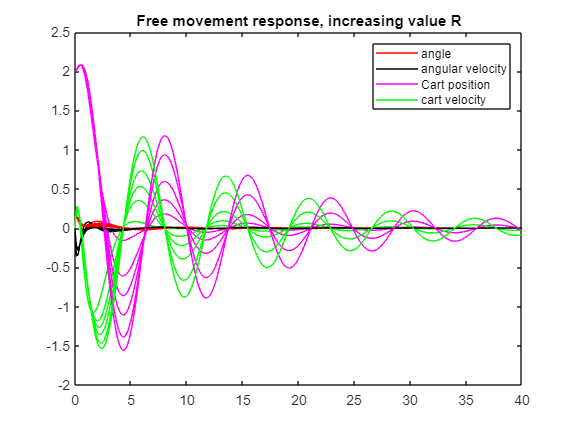

% Provide the code, an animation of the system the plots of the state evolution

listSys=cell(1,6);
 %listSys{i}=c2d(sysC,S(i));

 R =[1 5 10 20 50 100];
% R=[10]
for i =1:size(R,2)
[K] = dlqr(A,B,Q,R(i))
D=sysTD.D;
Ac = [(A-B*K)];
Bc = [B];
Cc = [C];
Dc = [D];
theta=deg2rad(10);
sysTD.A=Ac;
xinit=[theta 0 2 0 ];

[y, tOut]= initial(sysTD, xinit);

plot(tOut,y(:,1),'Color','r');
hold on
plot(tOut,y(:,2),'Color','k');
plot(tOut,y(:,3),'Color','m');
plot(tOut,y(:,4),'Color','g');

title('Free movement response, increasing value R');
legend('angle','angular velocity','Cart position','cart velocity');
xlim([0 40]);



end

Increasing value, the convergence is slower.

K =   -28.0000   -7.1043    0.0434   -1.4067


K =   -36.1940   -9.3152   -0.3733   -3.0580


K =   -42.0206  -10.9170   -0.7336   -4.2188


K =   -49.9683  -13.1218   -1.2428   -5.7807


K =   -64.8065  -17.2666   -2.1985   -8.6515


K =   -80.0516  -21.5413   -3.1735  -11.5666


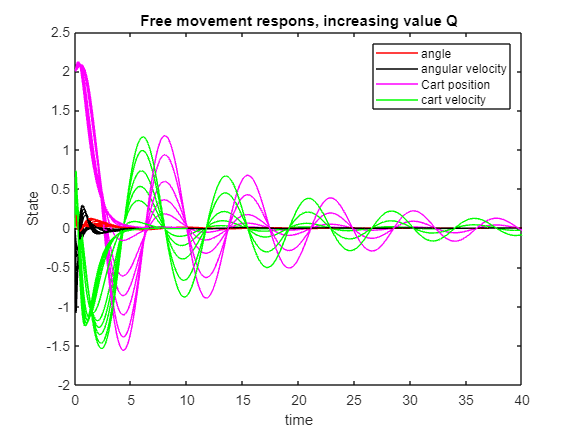

qi=[1 5 10 20 50 100];

for i =1:6
Q = [qi(i) 0 0 0; 0 qi(i) 0 0;0 0 qi(i) 0;0 0 0 qi(i)];
[K] = dlqr(A,B,Q,R(1))

D=sysTD.D;
Ac = [(A-B*K)];
Bc = [B];
Cc = [C];
Dc = [D];
theta=deg2rad(10);
sysTD.A=Ac;
xinit=[theta 0 2 0 ];

[y, tOut]= initial(sysTD, xinit);

plot(tOut,y(:,1),'Color','r');
hold on
plot(tOut,y(:,2),'Color','k');
plot(tOut,y(:,3),'Color','m');
plot(tOut,y(:,4),'Color','g');

title('Free movement respons, increasing value Q');
legend('angle','angular velocity','Cart position','cart velocity');
xlim([0 40]);
ylabel('State');
xlabel('time');
end

% Answer: (Provide the code, an animation of the system the plots of the state evolution)
         % cleaning the workspace

         clc 
         clear all
         sympref('default')

ans = struct with fields:
           FourierParameters: [1    -1]
           HeavisideAtOrigin: 1/2
            AbbreviateOutput: 1
               TypesetOutput: 1
         FloatingPointOutput: 0
      PolynomialDisplayStyle: 'default'
    MatrixWithSquareBrackets: 0


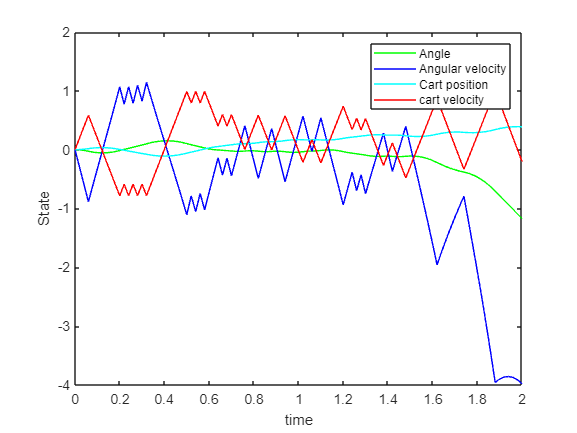

syms theta dt pc dpc
format short
syms u g mc mp l mu_p
load('U.mat');
syms f1(theta, dt, pc , dpc) f2(theta, dt, pc , dpc)


f1(theta, dt, pc , dpc)=(((g*sin(theta)+cos(theta)*(((-u-mp*l*(dt^2)*sin(theta))/(mc+mp)))-(mu_p*dt)/(mp*l)))/(l*(4/3-(mp*(cos(theta)^2)/(mc+mp)))));

f2(theta, dt, pc , dpc)=(u+mp*l*(((dt)^2)*sin(theta)-(f1(pc, dpc, theta, dt))*cos(theta)))/(mc+mp);
f_x=jacobian([dt;f1;dpc;f2],[theta;dt;pc;dpc]);
g_x=jacobian([dt;f1;dpc;f2],[u]);

%evaluating A matrix after linearization
pc=0;
dpc=0;
theta=0;
dt=0;
A1=eval(f_x);
B1=eval(g_x);



n=size(A1);
value=[g, mp, mc, mu_p, l];
A1=double(subs(A1,value,[9.8 0.1 1 0.000002 0.5]));

B1=double(subs(B1,value,[9.8 0.1 1 0.000002 0.5]));
sys=ss(A1,B1,eye(n),0);
sysTD=c2d(sys, 0.02);

t_span= 0:0.02:2;

nTime     = length(t_span);


x=[0 ;0; 0 ;0];


y(1, :) = x;
for i=1:nTime-1

y(i+1,:)=linearize(x,sysTD.A,sysTD.B,U(i));
x=y(i+1,:)';
end

figure;
plot(t_span,y(:,1),'g');
hold on
plot(t_span,y(:,2),'b');

plot(t_span,y(:,3),'c');

plot(t_span,y(:,4),'r');
legend('Angle','Angular velocity','Cart position','cart velocity');%'Position cart','velocity','angle','angular velocity','best'
ylabel('State');
xlabel('time');

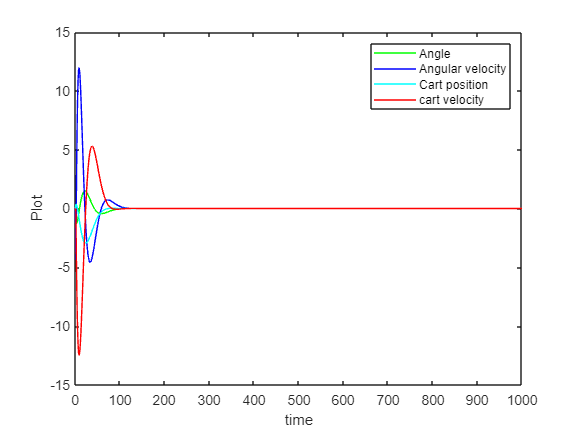

Q = [1 0 0 0; 0 1 0 0;0 0 700 0;0 0 0 1];
R = 1;
t_span=0:0.02:19.98;
[K] = dlqr(sysTD.A,sysTD.B,Q,R);
U_opt=zeros(length(U),1);

theta=deg2rad(0.3);

xinit=[theta 0 0 0 ];
nTime=length(U_opt);







y(1, :) = xinit;
for i=1:nTime-1
U_opt(i)=-K*y(i,:)';
y(i+1,:)=linearize1(x,sysTD.A,sysTD.B,i,U_opt(i),K);
x=y(i+1,:)';
end

figure;
plot(y(:,1),'g');
hold on
plot(y(:,2),'b');

plot(y(:,3),'c');

plot(y(:,4),'r');
legend('Angle','Angular velocity','Cart position','cart velocity');%'Position cart','velocity','angle','angular velocity','best'
ylabel('Plot');
xlabel('time');

5. Simulate the non-linear cart and pole system controlled by the previously obtained LQR. Plot the significant behaviors

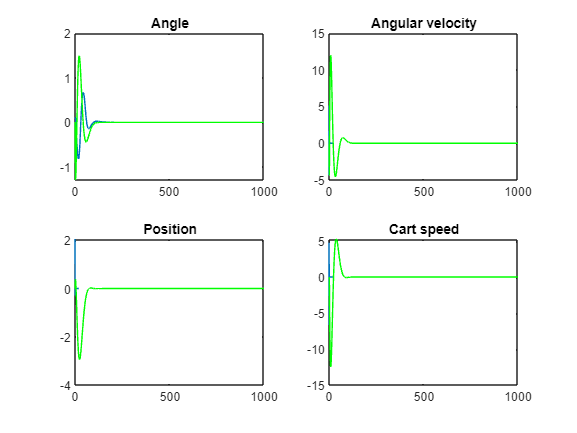

% Provide the code, an animation of the system the plots of the state evolution


% constants definition
g = 9.8; % gravitational acceleration
mc = 1;   % cart mass [kg]
l = 0.5; % half-pole length [m]
mp = 0.1; % pole mass [kg]
mup = 0.000002; % pole friction coefficient

theta0 = 0.1;
x0 = 1;
dot_x0 = 0.8;
dot_theta0 = 1.5;

t2=0;
conds=[theta0, dot_theta0, x0, dot_x0];
X_nl = conds';

%U=U_opt;
%N=length(U);
u=zeros(size(nTime));

timestep = 0.02;

for i = 1:nTime
    t1 = t2;
    t2 = t2+timestep;
    time = [t1, t2];
    u(i)=-K*X_nl(:,i);
    [t,state] = ode45(@(t,x)solving1(t, x, g, u(i), mp, l, mc, mup), time, conds);
    tp = find(t == t2);
    conds = state(tp,:);
    X_nl = [X_nl, conds'];
end

tfin = timestep*length(X_nl)-timestep;
figure()
subplot(2,2,1)
plot(X_nl(1,:))
hold on;
plot(y(:,1),'g');
title('Angle');
subplot(2,2,2)
plot(0:timestep:tfin,X_nl(2,:))
hold on;
plot(y(:,2),'g');
title('Angular velocity');
subplot(2,2,3)
plot(0:timestep:tfin,X_nl(3,:))
hold on;
plot(y(:,3),'g');
title('Position');
subplot(2,2,4)
plot(0:timestep:tfin,X_nl(4,:))
hold on;
plot(y(:,4),'g');
title('Cart speed');

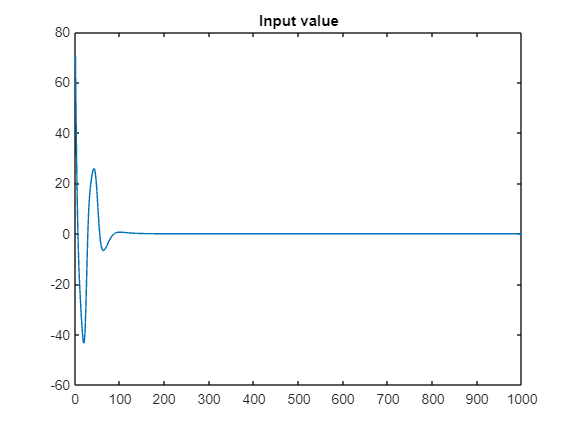

figure()
plot(u)
title('Input value');

6. Comment results obtained in the two simulations

% Arguing the answer

When it comes to non-linear systems, LQR can be applied if the linearized model is accurate enough for the operating conditions of interest. However, the stability guarantees of LQR do not directly transfer to the non-linear system.

LQR may provide effective stabilization for a non-linear system within a limited range of operating conditions, changing for example initial condition. Beyond that range or in the presence of significant non-linearities, the linearized model may not accurately represent the system, and the LQR controller might not perform as expected.

Changing the value of initial condition to an angle of, for example 0.1 rad (row 249) and setting the other statesto 0 like the previous point , the input value will decrease till 9 N respecting the constraints of the project..

Secondly, in the previous point ,the gain term in the Q matrix regarding the position is choosed far greater than the others that's because otherwise, the zero state for the position and consequently velocity of the cart will not be reached.(Try to substitute 1 instead of 700 in 203).